# E10

# Característiques locals I

#### HOG

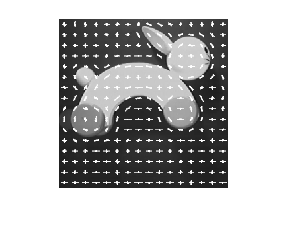

close all
Im = imread("rabbit.jpg");
Im = imresize(Im,[256 256]);

[HOG, HOGVec] = extractHOGFeatures(Im,'CellSize',[16 16],'BlockSize',[3 3],'NumBins',9);
imshow(Im)
hold on
plot(HOGVec);

#### Busquem un retall per HOG

[c, f] = getpts;
rect = [c-24,f-24,48,48];
Retall = imcrop(Im,rect);
figure
imshow(Retall)
HOGR= extractHOGFeatures(Retall,'CellSize',[16 16],'BlockSize',[3 3],'NumBins',9);

Unrecognized function or variable 'Retall'.

FIG = reshape(HOG,[81,14*14])';

Semblanca = zeros( [14*14,1]);
for i = 1:14*14
    Semblanca(i) = sum(min(FIG(i,:), HOGR)); % similitud per interseccio de l'histograma
end

[val, pos_block] = max(Semblanca);

% Ex: dibuixar un rectangle a la posicio de pos_black

#### Diferenciar histogrames de color

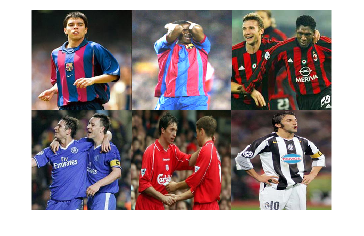

close all

im = imresize(imread('team1.jpg'), [256 256]);
im1 = imresize(imread('team2.jpg'), [256 256]);
im2 = imresize(imread('team5.jpg'), [256 256]);
im3 = imresize(imread('team11.jpg'), [256 256]);
im4 = imresize(imread('team12.jpg'), [256 256]);
im5 = imresize(imread('team8.jpg'), [256 256]);

montage({im,im1,im2,im3,im4,im5});

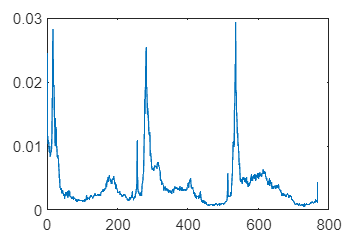



h = Calcular_Histograma_rg(im);
h1 = Calcular_Histograma_rg(im1);
h2 = Calcular_Histograma_rg(im2);
h3 = Calcular_Histograma_rg(im3);
h4 = Calcular_Histograma_rg(im4);
h5 = Calcular_Histograma_rg(im5);

plot(h)

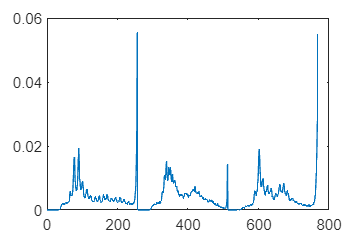

plot(h1);

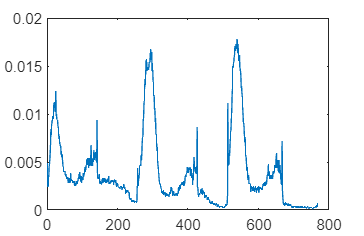

plot(h2);

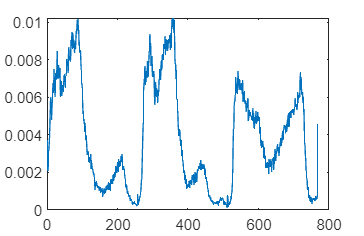

plot(h3);

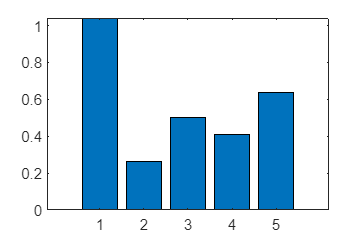


S(1) = Calcular_Similitud(h,h1);
S(2) = Calcular_Similitud(h,h2);
S(3) = Calcular_Similitud(h,h3);
S(4) = Calcular_Similitud(h,h4);
S(5) = Calcular_Similitud(h,h5);

bar(S);

function [h] = Calcular_Histograma_rg(im)
    nbins = 256;
    h1r = imhist(im(:,:,1), nbins) / numel(im(:,:,1));
    h1g = imhist(im(:,:,2), nbins) / numel(im(:,:,2));
    h1b = imhist(im(:,:,3), nbins) / numel(im(:,:,3));
    h = [h1r; h1g; h1b];
end

function [Sim] = Calcular_Similitud(h1,h2)
    Sim = sum((h1 - h2).^2 ./ (h1 + h2)) / 2;
end



% function [h] = Calcular_Histograma_rg(im)
%     nbins = 256;
%     h = histcounts2(im(:,:,1), im(:,:,2), nbins, 'Normalization', 'probability');
% end
% 
% function [Sim] = Calcular_Similitud(h,h1)
%     divKL = sum(h .* log(h ./ h1) + h1 .* log(h1 ./ h));
%     Sim = exp(-0.5 * divKL);
% end